# Discretization of Signals Tutorial

#### Rev. 2022: Logan Mathews, adapted from Kevin Leete

Digital signal processing typically starts with digitization/discretization of a continuous signal. Most of the time, the signals we are measuring are continuous- think about acoustic pressure. It's amplitude can be any value, and it has a value for every possible point in time. However, we have to discretize the signal into points- both in time and in amplitude. We're limited by how often we can sample in time, and also with what precision we can represent a number. Often times, you'll see this represented in specifications of your data aquisition hardware in terms of a maximum sampling rate/frequency (how often you can sample in time), and a digitization specification (like 8-bit, 24-bit, etc...) which represents how accurately (think how many decimal places) you can represent a number as. In this tutorial, we'll explore how digitization works and how it affects your sampled signal that you will do analyses on.

## Making a Signal

Here, we're going to create a pseudo-continuous signal (we're doing this in a computer, so it's actually discrete, but we'll make the resoluation really fine to "emulate" a continuous signal). What is going on here in the code isn't important.

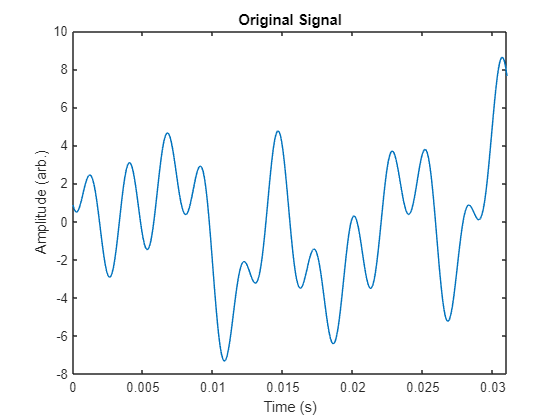

T = 0.031;
dt = 0.0001;
t = (0:dt:T).';
ap = [2 3 1.5 2.5];
phis = [0 pi/4 2*pi/3 pi];
effs = [31.25 125 187.5 375];
x = sum(real(ap.*exp(1j*(phis+2*pi*effs.*t))),2);
figure
plot(t,x)
xlabel('Time (s)')
ylabel('Amplitude (V)')
title('Original Signal')
xlim([0,T])

## Sampling the Waveform

Now that we have our "continuous" signal- like what the voltage signal from the microphone would be, we can "sample" it like a data acquisition system would. For this, we're going to have to specify some properties of our data acquisition system, specifically what its sampling rate, quantization bit depth, and input voltage range are.

You can try playing with these quantities to see the result on the sampling, relative error, and SNR.

### DAQ Specifications

fs = 1000; % Sample Rate of DAQ, Hz
N = 4; % Bit Depth of Digizer, 2-6 works good for visualizing
Vpp = 18; % Input voltage range, peak-to-peak, V

### Sample the Signal

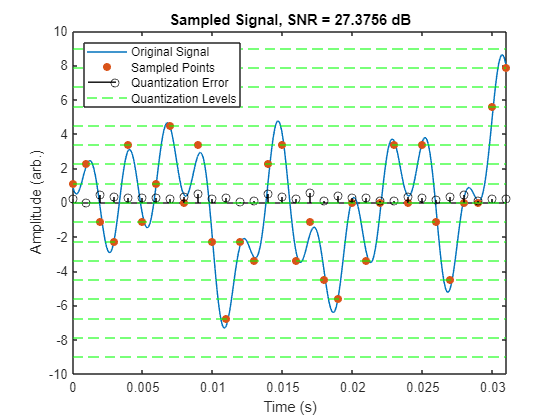

dtDAQ = 1/fs; % Temporal length of each sample, sec
tSamp = t(1:dtDAQ/dt:end);
xSamp = x(1:dtDAQ/dt:end);

qLevel = Vpp/(2^N); % Find quanized voltage level resolution
vLevels = [-Vpp/2:qLevel:Vpp/2]; % Quantization voltage levels, V
numLevels = length(vLevels); % Find total number of quantization levels

[error,ind] = min(abs(xSamp-vLevels),[],2); % This finds the nearest quantization levels to the sample point
xQuant = vLevels(ind)';

SNR = 10*log10(var(x)/var(error)); % Determine the SNR of this sampled signal

close
figure
plot(t,x)
hold on
scatter(tSamp,xQuant,'filled')
stem(tSamp,error,'k')
yline(vLevels,'g--')
legend('Original Signal','Sampled Points','Quantization Error','Quantization Levels','Location','NorthWest')
ylim([-10 10])
xlabel('Time (s)')
ylabel('Amplitude (V)')
title(['Sampled Signal, SNR = ',num2str(SNR),' dB'])
xlim([0,T])

## Things to Think About

- What happens to the relative error/SNR when you change the bit depth? What about when you change the voltage range?

- Does your voltage range matter? Why?

- We assign a signal-to-noise ratio (SNR) to our quantization. We typically talk about SNR in reference to two signals, one being the signal we are interested in, and the other being a noise signa. In this example, what is the signal of interest, and what is the noise signal? 

- Does it matter what your voltage range is if you have a large bit depth digitizer?